% Modelling ML

clear; clc; % Clear workspace

% Load train and test data
train = readtable('train.csv');
test = readtable('test.csv');

% Convert to matrix
train = train{:,:};
test = test{:,:};

% Split into target and features 
X_train = train(:, 2:end);
y_train = train(:, 1);

X_test = test(:, 2:end);
y_test = test(:, 1);


% Load oversampled train data
X_train_SMOTE = readtable('X_train_SMOTE.csv');
y_train_SMOTE = readtable('y_train_SMOTE.csv');

X_train_SMOTE = X_train_SMOTE{:,:};
y_train_SMOTE = y_train_SMOTE{:,:};

% Load PCA X_train and X_test data
X_train_PCA = readtable('X_train_PCA.csv');
X_test_PCA = readtable('X_test_PCA.csv');

X_train_PCA = X_train_PCA{:,:};
X_test_PCA = X_test_PCA{:,:};

rng(1) % for reproducability

% ********** 1) Train / Test Baseline Models **********

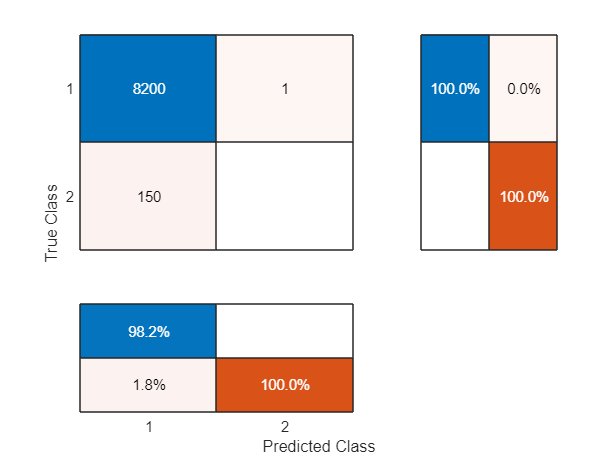

accuracy = 0.9819

precision = 0

recall = 0

specificity = 0.9999

fb = 0

% 1a) Baseline Decision Tree with default parameters
% Train
dt_base = fitctree(X_train, y_train, 'Reproducible', 1, 'prior', 'empirical', 'MaxNumSplits', 10, 'MinLeafSize', 1);
% Evaluate baseline tree
test_model(dt_base, X_test, y_test)

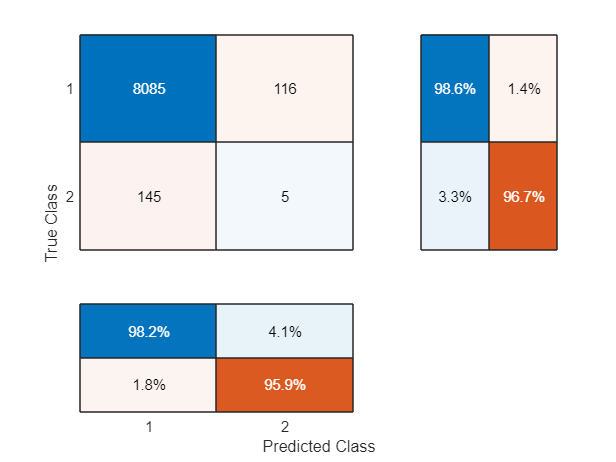

accuracy = 0.9687

precision = 0.0413

recall = 0.0333

specificity = 0.9859

fb = 0.0369

% 1b) Baseline KNN
% Train
knn_base = fitcknn(X_train, y_train, 'Standardize', 1, 'Prior', 'empirical', 'NumNeighbors', 1, 'Distance', 'euclidean', 'DistanceWeight', 'equal'); 
% Evaluate baseline knn
test_model(knn_base, X_test, y_test)

% ********** 2) Hyperparameter Tuning Models (CV = k-fold, loss = accuracy) **********

% CV SPLITS: Define a random partition of data (fixes the train and validation set)
[nrow, ncol] = size(X_train);
c = cvpartition(nrow,'KFold', 20);

% DECISION TREE: Define vars and range
prior = optimizableVariable('prior', {'uniform','empirical'},'Type','categorical'); % default: 'empirical'
MaxNumSplit = optimizableVariable('MaxNumSplit',[1, 30],'Type','integer');  % default: 10
MinLeafSize = optimizableVariable('MinLeafSize', [1, 30], 'Type', 'integer');  % default: 1

ParamsDT = [prior, MaxNumSplit, MinLeafSize];

% KNN: Define vars and range
prior = optimizableVariable('prior', {'uniform','empirical'},'Type','categorical'); % default: 'empirical'
n = optimizableVariable('n',[1,20],'Type','integer'); % defualt: 1
dst = optimizableVariable('dst', {'euclidean', 'cosine', 'correlation'},'Type','categorical'); % default: euclidean
dstWeight = optimizableVariable('dstWeight', {'equal','inverse', 'squaredinverse'},'Type','categorical');  % default: equal

ParamsKNN = [prior; n; dst; dstWeight];

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        prior |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |     0.23496 |      1.1173 |     0.23496 |     0.23496 |      uniform |           20 |           22 |
|    2 | Best   |    0.014759 |      1.1467 |    0.014759 |      0.1234 |    empirical |            9 |           16 |
|    3 | Accept |     0.24486 |      1.1591 |    0.014759 |    0.014776 |      uniform |           23 |           27 |
|    4 | Accept |     0.22989 |     0.76738 |    0.014759 |     0.01477 |      uniform |            2 |           23 |
|    5 | Accept |    0.014759 |      1.3943 |   

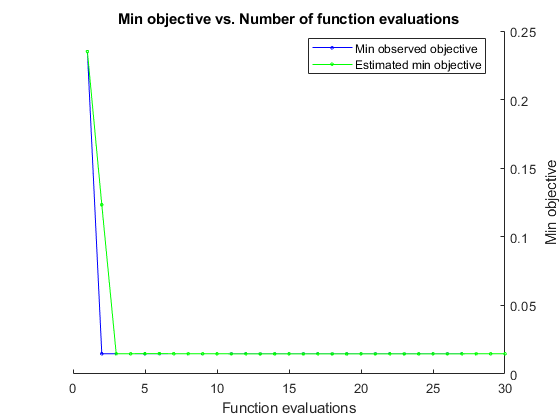


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 43.2183 seconds
Total objective function evaluation time: 24.1254

Best observed feasible point:
      prior      MaxNumSplit    MinLeafSize
    _________    ___________    ___________

    empirical         9             16     

Observed objective function value = 0.014759
Estimated objective function value = 0.014795
Function evaluation time = 1.1467

Best estimated feasible point (according to models):
      prior      MaxNumSplit    MinLeafSize
    _________    ___________    ___________

    empirical         2             30     

Estimated objective function value = 0.014735
Estimated function evaluation ti

% 2a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = accuracy)
% 2a-i) Define loss function
loss = @(params)kfoldLoss(fitctree(X_train, y_train, 'CVPartition', c, 'Reproducible', 1,...
                                     'prior', char(params.prior), ...
                                     'MaxNumSplits',params.MaxNumSplit, ...
                                     'MinLeafSize',params.MinLeafSize));

% 2a-ii) Optimize model
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

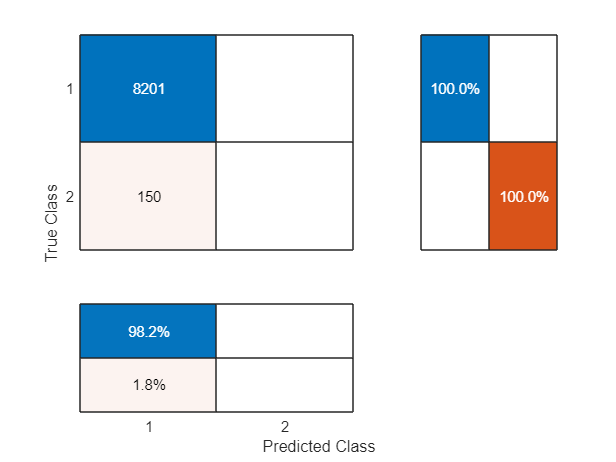

accuracy = 0.9820

precision = NaN

recall = 0

specificity = 1

fb = 0

% 2a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train, y_train, 'Reproducible', 1,...
    'prior', char(z.prior), ...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 2a-iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        prior |            n |          dst |    dstWeight |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |              |
|===================================================================================================================================|
|    1 | Best   |     0.37348 |      5.7011 |     0.37348 |     0.37348 |      uniform |           11 |    euclidean |        equal |
|    2 | Best   |    0.016465 |      5.4205 |    0.016465 |     0.18181 |    empirical |            3 |    euclidean |        equal |
|    3 | Accept |     0.37712 |       5.484 |    0.016465 |    0.031428 |      uniform |           11 |       cosine |      inverse |
|    4 | Accept |    0.028589 |      5.3197 |    0.016465 |   

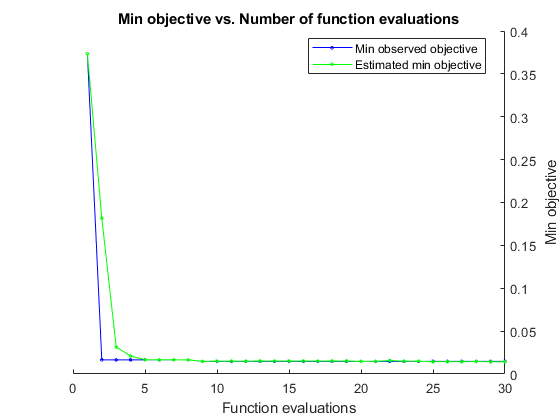


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 244.6609 seconds
Total objective function evaluation time: 223.8906

Best observed feasible point:
      prior      n        dst        dstWeight
    _________    _    ___________    _________

    empirical    9    correlation      equal  

Observed objective function value = 0.014759
Estimated objective function value = 0.020181
Function evaluation time = 5.9629

Best estimated feasible point (according to models):
      prior      n         dst        dstWeight
    _________    __    ___________    _________

    empirical    20    correlation  

% 2b) KNN: Bayesian Optimization (CV = k-fold, loss = accuracy)
% 2b-i) Define loss function
loss = @(params)kfoldLoss(fitcknn(X_train, y_train, 'Standardize', 1, 'CVPartition', c, ...
            'prior', char(params.prior), ...
            'NumNeighbors', params.n, ...
            'Distance', char(params.dst), ...
            'DistanceWeight',char(params.dstWeight)));

% 2b-ii) Optimize model
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

accuracy = 0.9820

precision = NaN

recall = 0

specificity = 1

fb = 0

% 2b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train, y_train, 'Standardize', 1, ...
    'prior', char(z.prior), ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst), ...
    'DistanceWeight',char(z.dstWeight));

% 2b-iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

% ********** 3) Hyperparameter Tuning Models (CV = k-fold, loss = f-beta) **********

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        prior |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |           1 |      1.8331 |           1 |           1 |    empirical |           24 |            5 |
|    2 | Best   |     0.92742 |     0.78261 |     0.92742 |     0.93328 |      uniform |            2 |           17 |
|    3 | Best   |     0.91406 |      1.0882 |     0.91406 |     0.91412 |      uniform |            9 |           25 |
|    4 | Accept |           1 |       1.005 |     0.91406 |     0.91409 |    empirical |            2 |           11 |
|    5 | Accept |     0.91664 |      2.0172 |   

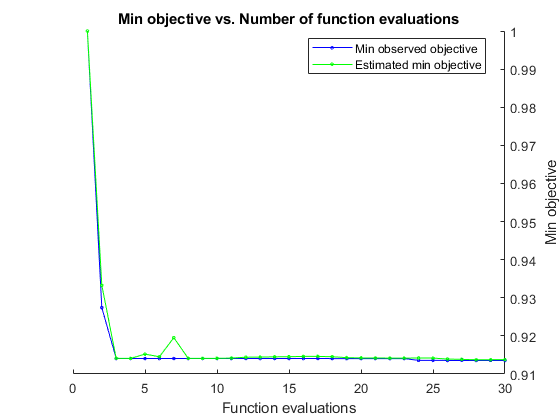


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 48.5447 seconds
Total objective function evaluation time: 33.9905

Best observed feasible point:
     prior     MaxNumSplit    MinLeafSize
    _______    ___________    ___________

    uniform        16             27     

Observed objective function value = 0.91356
Estimated objective function value = 0.91379
Function evaluation time = 0.97549

Best estimated feasible point (according to models):
     prior     MaxNumSplit    MinLeafSize
    _______    ___________    ___________

    uniform        16             30     

Estimated objective function value = 0.91379
Estimated function evaluation time = 0.98633



% 3a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = f-beta)
% 3a-i) Define loss function
loss = @(params)fb_loss_dt_cv(params,X_train,y_train, c); % see helper function

% 3a-ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

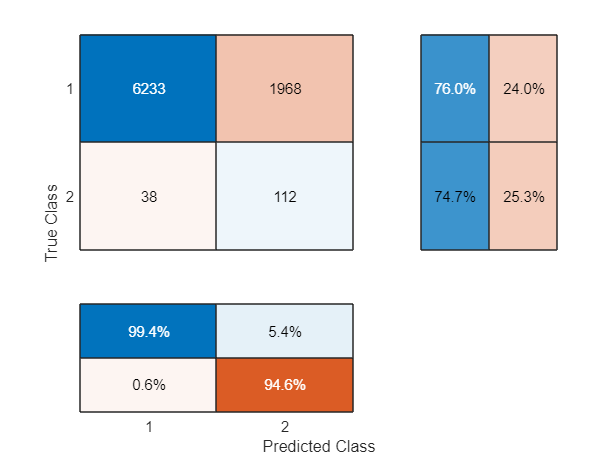

accuracy = 0.7598

precision = 0.0538

recall = 0.7467

specificity = 0.7600

fb = 0.1004


% 3a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train, y_train, 'Reproducible', 1, ...
    'prior', char(z.prior), ...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 3a-iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        prior |            n |          dst |    dstWeight |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |              |
|===================================================================================================================================|
|    1 | Best   |     0.92032 |      8.5522 |     0.92032 |     0.92032 |      uniform |            6 |    euclidean |      inverse |
|    2 | Accept |     0.92467 |      9.4594 |     0.92032 |     0.92078 |      uniform |           18 |  correlation |      inverse |
|    3 | Accept |           1 |       7.524 |     0.92032 |     0.94831 |    empirical |           10 |    euclidean |      inverse |
|    4 | Accept |           1 |      7.3037 |     0.92032 |   

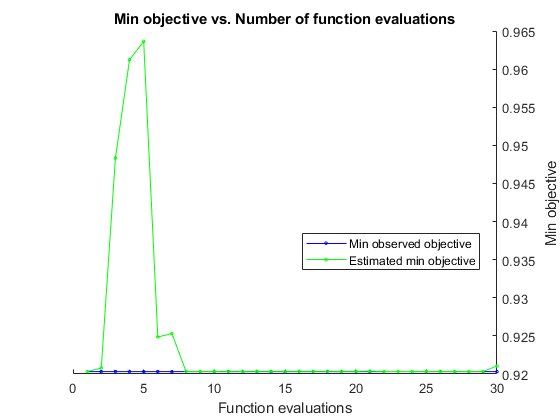


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 211.1106 seconds
Total objective function evaluation time: 195.4163

Best observed feasible point:
     prior     n       dst       dstWeight
    _______    _    _________    _________

    uniform    6    euclidean     inverse 

Observed objective function value = 0.92032
Estimated objective function value = 0.92229
Function evaluation time = 8.5522

Best estimated feasible point (according to models):
     prior     n      dst      dstWeight
    _______    __    ______    _________

    uniform    12    cosine      equal  

Estimated objective fu

% 3b) KNN: Bayesian Optimization (CV = k-fold, loss = f-beta)
% 3b-i) Define loss function
loss = @(params)fb_loss_knn_cv(params,X_train,y_train, c); % see helper function

% 3b-ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

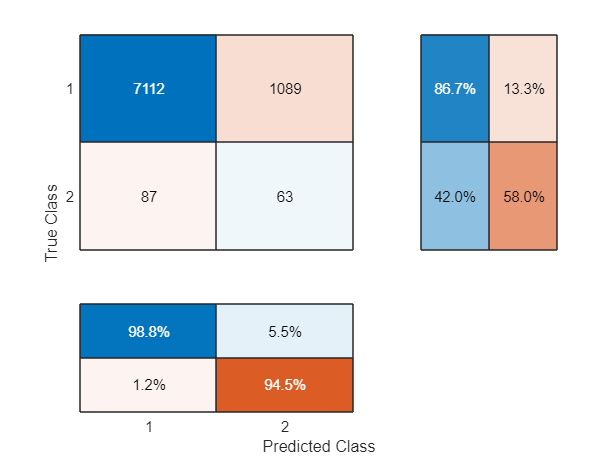

accuracy = 0.8592

precision = 0.0547

recall = 0.4200

specificity = 0.8672

fb = 0.0968


% 3b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train, y_train, 'Standardize', 1, ...
    'prior', char(z.prior), ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst), ...
    'DistanceWeight',char(z.dstWeight));

% 3b-iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

% ********** 4) Hyperparameter Tuning Models (CV = statify, loss = f-beta) **********

% CV SPLITS (Stratified)
c_strat = cvpartition(y_train,'KFold', 20, 'Stratify', true);

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        prior |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |           1 |     0.66107 |           1 |           1 |    empirical |            4 |            2 |
|    2 | Best   |     0.91425 |     0.66692 |     0.91425 |     0.92059 |      uniform |            9 |           26 |
|    3 | Best   |     0.91331 |     0.76185 |     0.91331 |     0.91373 |      uniform |           17 |           15 |
|    4 | Accept |           1 |     0.82007 |     0.91331 |     0.91369 |    empirical |           28 |            9 |
|    5 | Accept |           1 |     0.89405 |   

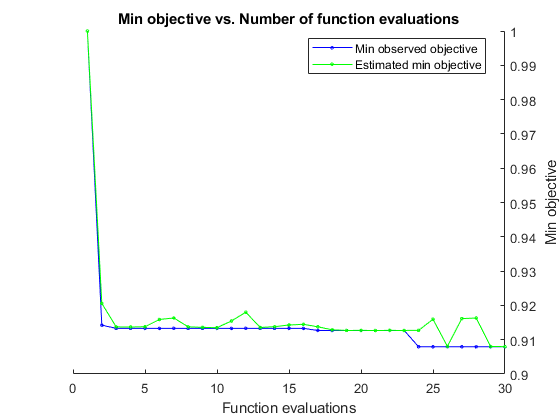


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 29.5203 seconds
Total objective function evaluation time: 18.5988

Best observed feasible point:
     prior     MaxNumSplit    MinLeafSize
    _______    ___________    ___________

    uniform         4              1     

Observed objective function value = 0.90794
Estimated objective function value = 0.90799
Function evaluation time = 0.57578

Best estimated feasible point (according to models):
     prior     MaxNumSplit    MinLeafSize
    _______    ___________    ___________

    uniform         4              1     

Estimated objective function value = 0.90799
Estimated function evaluation time = 0.56253



% 4a) Decision Tree: Bayesian Optimization (CV = statify, loss = f-beta)
% 4a-i) Define loss function
loss = @(params)fb_loss_dt_cv(params,X_train,y_train, c_strat); % see helper function

% 4a-ii) Optimize model
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

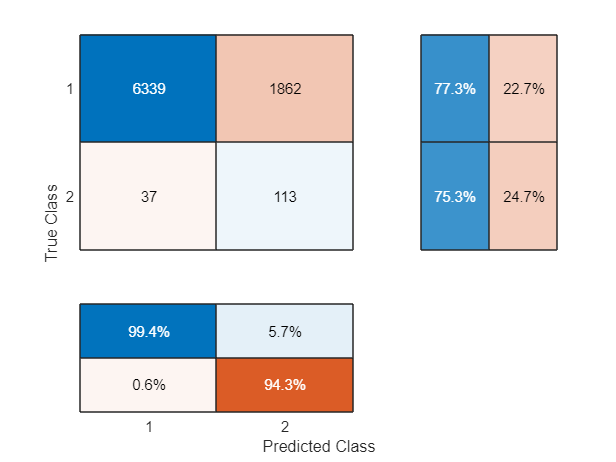

accuracy = 0.7726

precision = 0.0572

recall = 0.7533

specificity = 0.7730

fb = 0.1064


% 4a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train, y_train, 'Reproducible', 1, ...
    'prior', char(z.prior), ...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 4a-iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

% 4b) KNN: Bayesian Optimization (CV = statify, loss = f-beta)
disp('***** Hyperparameter Tuning KNN (CV = statify, loss = f-beta) *****')

***** Hyperparameter Tuning KNN (CV = statify, loss = f-beta) *****



% 4b-i) Define loss function
loss = @(params)fb_loss_knn_cv(params,X_train,y_train, c_strat) % see helper function

loss = function_handle with value:
    @(params)fb_loss_knn_cv(params,X_train,y_train,c_strat)


|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        prior |            n |          dst |    dstWeight |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |              |
|===================================================================================================================================|
|    1 | Best   |     0.96488 |      4.9626 |     0.96488 |     0.96488 |      uniform |            1 |    euclidean |      inverse |
|    2 | Accept |     0.96883 |       4.888 |     0.96488 |     0.96537 |    empirical |            9 |       cosine | squaredinver |
|    3 | Accept |     0.99633 |      5.0023 |     0.96488 |     0.96667 |    empirical |           20 |       cosine |      inverse |
|    4 | Accept |      0.9898 |      5.0524 |     0.96488 |   

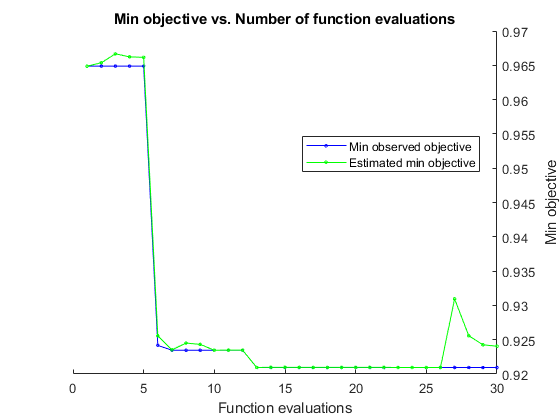


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 198.9565 seconds
Total objective function evaluation time: 186.0024

Best observed feasible point:
     prior     n       dst       dstWeight
    _______    _    _________    _________

    uniform    7    euclidean      equal  

Observed objective function value = 0.92094
Estimated objective function value = 0.93378
Function evaluation time = 6.672

Best estimated feasible point (according to models):
     prior     n         dst        dstWeight
    _______    __    ___________    _________

    uniform    12    correlation      equal  

Estimate


% 4b-ii) Optimize model
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

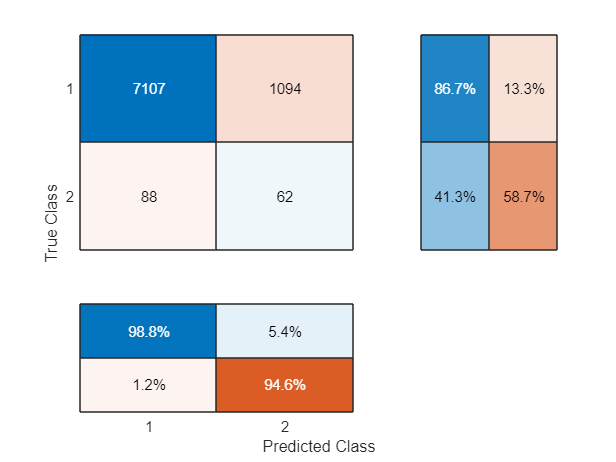

accuracy = 0.8585

precision = 0.0536

recall = 0.4133

specificity = 0.8666

fb = 0.0949


% 4b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train, y_train, 'Standardize', 1, ...
    'prior', char(z.prior), ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst), ...
    'DistanceWeight',char(z.dstWeight));

% 4b-iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

% ********** 5) Hyperparameter Tuning Models (CV = k-fold, loss = f-beta, SMOTE) **********

% CV SPLITS SMOTE:
[nrow, ncol] = size(X_train_SMOTE);
c_SMOTE = cvpartition(nrow,'KFold', 20);

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        prior |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |     0.08742 |      2.0204 |     0.08742 |     0.08742 |    empirical |           24 |            5 |
|    2 | Accept |     0.12902 |      1.0376 |     0.08742 |    0.090778 |      uniform |            2 |           17 |
|    3 | Accept |      0.1104 |      1.6283 |     0.08742 |     0.08749 |      uniform |            9 |           25 |
|    4 | Accept |     0.12902 |     0.95851 |     0.08742 |    0.087452 |    empirical |            2 |           11 |
|    5 | Accept |    0.089604 |      1.9351 |   

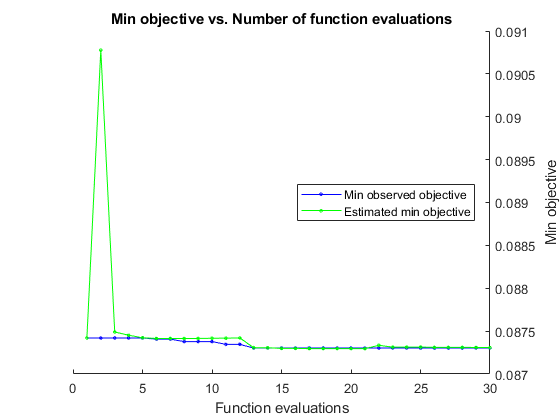


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 67.532 seconds
Total objective function evaluation time: 56.2903

Best observed feasible point:
     prior     MaxNumSplit    MinLeafSize
    _______    ___________    ___________

    uniform        30              1     

Observed objective function value = 0.087303
Estimated objective function value = 0.087321
Function evaluation time = 2.1224

Best estimated feasible point (according to models):
     prior     MaxNumSplit    MinLeafSize
    _______    ___________    ___________

    uniform        29              2     

Estimated objective function value = 0.087308
Estimated function evaluation time = 1.8804



% 5a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = f-beta, SMOTE)
% 5a-i) Define loss function
loss = @(params)fb_loss_dt_cv(params,X_train_SMOTE,y_train_SMOTE, c_SMOTE); % see helper function

% 5a-ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

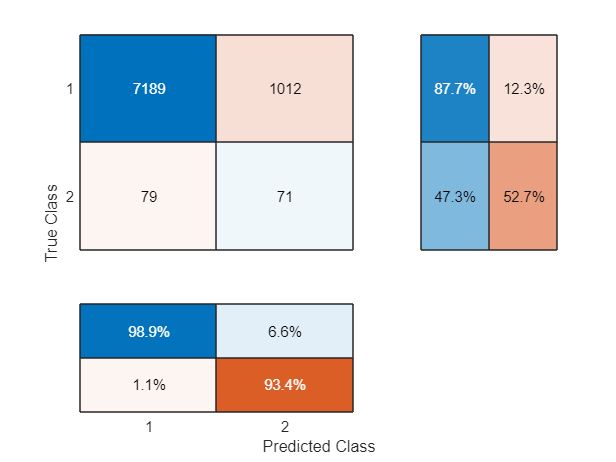

accuracy = 0.8694

precision = 0.0656

recall = 0.4733

specificity = 0.8766

fb = 0.1152


% 5a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train_SMOTE, y_train_SMOTE, 'Reproducible', 1, ...
    'prior', char(z.prior), ...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 5a-iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        prior |            n |          dst |    dstWeight |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |              |
|===================================================================================================================================|
|    1 | Best   |    0.012495 |      30.602 |    0.012495 |    0.012495 |      uniform |            6 |    euclidean |      inverse |
|    2 | Accept |    0.015838 |      36.404 |    0.012495 |    0.013039 |      uniform |           18 |  correlation |      inverse |
|    3 | Accept |    0.014438 |      24.893 |    0.012495 |    0.014251 |    empirical |           10 |    euclidean |      inverse |
|    4 | Accept |    0.014541 |       22.19 |    0.012495 |   

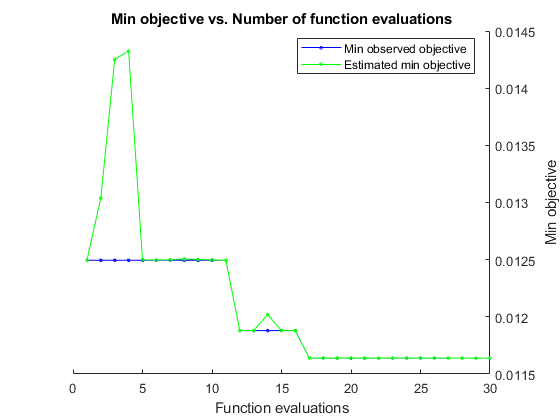


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 736.3284 seconds
Total objective function evaluation time: 700.0774

Best observed feasible point:
     prior     n     dst      dstWeight
    _______    _    ______    _________

    uniform    3    cosine      equal  

Observed objective function value = 0.011639
Estimated objective function value = 0.011639
Function evaluation time = 22.2301

Best estimated feasible point (according to models):
     prior     n     dst      dstWeight
    _______    _    ______    _________

    uniform    3    cosine      equal  

Estimated objective function va

% 5b) KNN: Bayesian Optimization (CV = k-fold, loss = f-beta, SMOTE)
% 5b-i) Define loss function
loss = @(params)fb_loss_knn_cv(params,X_train_SMOTE, y_train_SMOTE, c_SMOTE); % see helper function

% 5b-ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

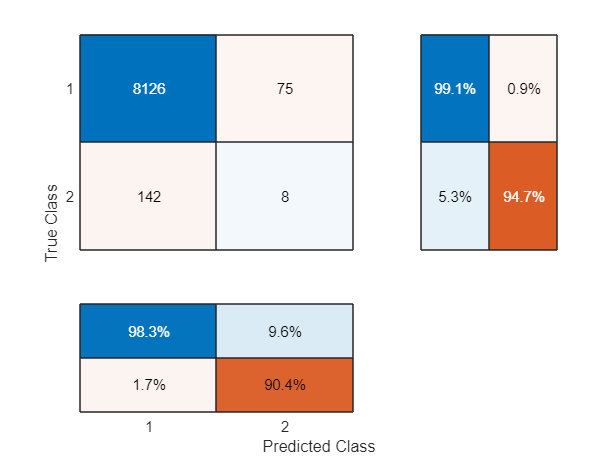

accuracy = 0.9740

precision = 0.0964

recall = 0.0533

specificity = 0.9909

fb = 0.0687


% 5b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train_SMOTE, y_train_SMOTE, 'Standardize', 1, ...
    'prior', char(z.prior), ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst), ...
    'DistanceWeight',char(z.dstWeight));

% 5b-iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

% ********** 6) Hyperparameter Tuning Models (CV = k-fold, loss = accuracy, SMOTE) **********

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        prior |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |     0.12058 |      1.1433 |     0.12058 |     0.12058 |      uniform |            5 |           20 |
|    2 | Best   |    0.091155 |      1.5349 |    0.091155 |    0.097151 |    empirical |           20 |           20 |
|    3 | Accept |     0.10632 |      1.3323 |    0.091155 |    0.096874 |    empirical |           14 |           22 |
|    4 | Accept |     0.12058 |      1.1242 |    0.091155 |    0.091158 |    empirical |            4 |           10 |
|    5 | Accept |     0.12058 |      1.1111 |   

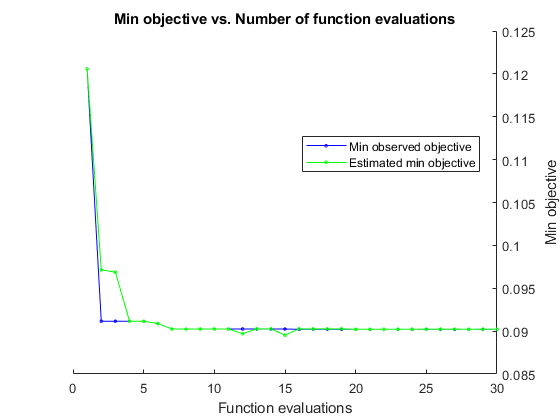


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 57.6505 seconds
Total objective function evaluation time: 46.4515

Best observed feasible point:
      prior      MaxNumSplit    MinLeafSize
    _________    ___________    ___________

    empirical        28              1     

Observed objective function value = 0.090213
Estimated objective function value = 0.090226
Function evaluation time = 1.5654

Best estimated feasible point (according to models):
      prior      MaxNumSplit    MinLeafSize
    _________    ___________    ___________

    empirical        28             30     

Estimated objective function value = 0.090226
Estimated function evaluation ti

% 6a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = accuracy, SMOTE)
% 6a-i) Define loss function
loss = @(params)kfoldLoss(fitctree(X_train_SMOTE, y_train_SMOTE, 'CVPartition', c_SMOTE, 'Reproducible', 1,...
                                     'prior', char(params.prior), ...
                                     'MaxNumSplits',params.MaxNumSplit, ...
                                     'MinLeafSize',params.MinLeafSize));

% 6a-ii) Optimize model
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

accuracy = 0.8694

precision = 0.0656

recall = 0.4733

specificity = 0.8766

fb = 0.1152

% 6a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train_SMOTE, y_train_SMOTE, 'Reproducible', 1,...
    'prior', char(z.prior), ...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 6a-iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        prior |            n |          dst |    dstWeight |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |              |
|===================================================================================================================================|
|    1 | Best   |    0.014402 |      19.941 |    0.014402 |    0.014402 |      uniform |            5 |  correlation | squaredinver |
|    2 | Accept |    0.014463 |      20.747 |    0.014402 |    0.014433 |    empirical |            6 |  correlation | squaredinver |
|    3 | Accept |    0.015117 |      23.331 |    0.014402 |    0.014403 |    empirical |            1 |    euclidean |      inverse |
|    4 | Accept |    0.014889 |      26.034 |    0.014402 |   

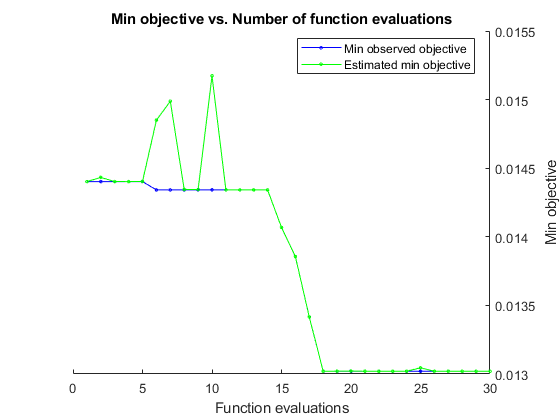


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 693.3202 seconds
Total objective function evaluation time: 657.2845

Best observed feasible point:
     prior     n     dst      dstWeight
    _______    _    ______    _________

    uniform    4    cosine     inverse 

Observed objective function value = 0.01302
Estimated objective function value = 0.013021
Function evaluation time = 26.866

Best estimated feasible point (according to models):
      prior      n     dst      dstWeight
    _________    _    ______    _________

    empirical    6    cosine     inverse 

Estimated objective functio

% 6b) KNN: Bayesian Optimization (CV = k-fold, loss = accuracy, SMOTE)
% 6b-i) Define loss function
loss = @(params)kfoldLoss(fitcknn(X_train_SMOTE, y_train_SMOTE, 'Standardize', 1, 'CVPartition', c_SMOTE, ...
            'prior', char(params.prior), ...
            'NumNeighbors', params.n, ...
            'Distance', char(params.dst), ...
            'DistanceWeight',char(params.dstWeight)));

% 6b-ii) Optimize model
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

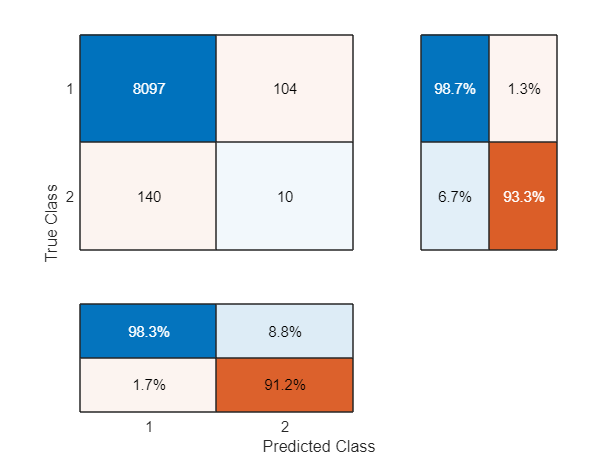

accuracy = 0.9708

precision = 0.0877

recall = 0.0667

specificity = 0.9873

fb = 0.0758

% 6b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train_SMOTE, y_train_SMOTE, 'Standardize', 1, ...
    'prior', char(z.prior), ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst), ...
    'DistanceWeight',char(z.dstWeight));

% 6b-iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

% ********** 7) Hyperparameter Tuning Models (CV = k-fold, loss = f-beta, PCA) **********

% 7a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = f-beta, PCA)
% 7a-i) Define loss function
loss = @(params)fb_loss_dt_cv(params,X_train_PCA,y_train, c); % see helper function

% 7a-ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

% 7a-iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train_PCA, y_train, 'Reproducible', 1, ...
    'prior', char(z.prior), ...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% 7a-iv) Evaluate final model on test data
test_model(dt_best, X_test_PCA, y_test)

% 7b) KNN: Bayesian Optimization (CV = k-fold, loss = f-beta, PCA)
% 7b-i) Define loss function
loss = @(params)fb_loss_knn_cv(params,X_train_PCA,y_train, c); % see helper function

% 7b-ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'GPActiveSetSize', 1000, 'Verbose',1);

% 7b-iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train_PCA, y_train, 'Standardize', 1, ...
    'prior', char(z.prior), ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst), ...
    'DistanceWeight',char(z.dstWeight));

% 7b-iv) Evaluate final model on test data
test_model(knn_best, X_test_OCA, y_test)

function test_model(model, X_test, y_test)
    y_pred = predict(model, X_test);
    cmat = confusionmat(y_test, y_pred);  % Confusion matrix
    cm = confusionchart(cmat);
    cm.RowSummary = 'row-normalized';
    cm.ColumnSummary = 'column-normalized';
    [accuracy, precision, recall, specificity, fb] = binary_eval_metrics(y_test, y_pred) 
end

% Decision tree loss loss function CV
function fb = fb_loss_dt_cv(params, X_train, y_train, cv_part)
        % Train model with selected parameters
        model = fitctree(X_train, y_train, 'CVPartition', cv_part, 'Reproducible', 1,...
             'prior', char(params.prior), ...
             'MaxNumSplits',params.MaxNumSplit, ...
             'MinLeafSize',params.MinLeafSize);
               
        % Calculate F1 score
        y_pred = kfoldPredict(model);
        [~, ~, ~, ~, fb] = binary_eval_metrics(y_train, y_pred);
        fb = 1-fb;  % Convert to f1-"loss"
end

% KNN function CV
function fb = fb_loss_knn_cv(params, X_train, y_train, cv_part)
        model = fitcknn(X_train, y_train, 'Standardize', 1, 'CVPartition', cv_part, ...
            'prior', char(params.prior), ...
            'NumNeighbors', params.n, ...
            'Distance', char(params.dst), ...
            'DistanceWeight',char(params.dstWeight));
        
        % Calculate F-beta score
        y_pred = kfoldPredict(model);   
        [~, ~, ~, ~, fb] = binary_eval_metrics(y_train, y_pred);
        fb = 1-fb;  % Convert to f1-"loss"
end

% Evaluation metrics for binary classification
function [acc, prec, rec, spec, fb] = binary_eval_metrics(y_test, y_pred)
    cmat = confusionmat(y_test, y_pred);
    tn = cmat(1,1);
    fn = cmat(2,1);
    tp = cmat(2,2);
    fp = cmat(1,2);

    % Statistics of interest for confusion matrix
    b = 1; % beta < 1 favours precision over recall.
    prec = tp / (tp + fp); % precision
    rec = tp / (tp + fn); % recall
    spec = tn / (tn + fp); % specificity
    acc = (tp + tn) / (tn + fn + tp + fp);
    fb = ((1+b^2)*tp) / ((1+b^2)*tp + b^2 * fp + fn); % (see https://en.wikipedia.org/wiki/F-score)
end
%#ok<*ASGLU,*NOPRT> 